clear;
s = tf('s')

s =
 
  s
 
연속시간 전달 함수입니다.
모델 속성


G = (s+1)/s*(s+2)*(s+3)

G =
 
  s^3 + 6 s^2 + 11 s + 6
  ----------------------
            s
 
연속시간 전달 함수입니다.
모델 속성


% (a)
zeta = 0.4;
Ts = 2

Ts = 2

wn = 4/(Ts*zeta)

wn = 5

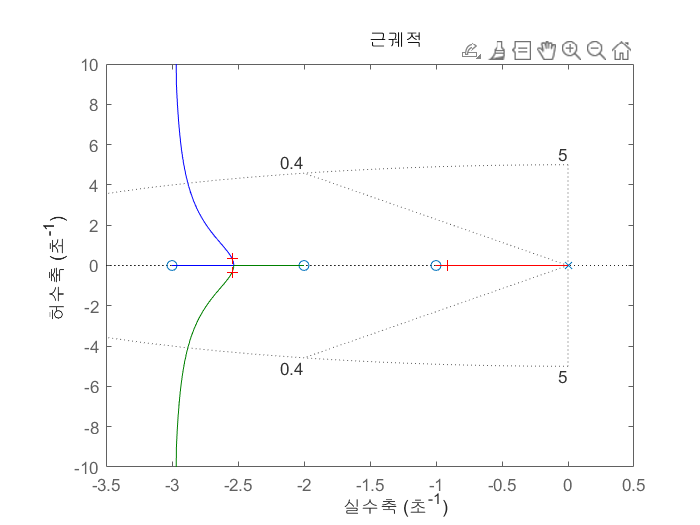

Select a point in the graphics window


selected_point = -2.5417 + 0.3474i

k = 4.3863

poles =   -2.5454 + 0.3471i
  -2.5454 - 0.3471i
  -0.9091 + 0.0000i


rlocus(G)
sgrid(zeta,wn)

[k, poles] = rlocfind(G) %rlocfind 함수를 사용해 zeta>0.4 이면서 wn 안에 있는 것을 찾아 k를 도출한다

k % 나는 k = 4.3863을 넣었다.

k = 4.3863

% (b)
PO = 100*exp(-zeta*pi/sqrt(1-zeta^2)) %overshoot이 25%를 넘으면 안 된다.

PO = 25.3827

sys_cl = feedback(k*G,1)

sys_cl =
 
  4.386 s^3 + 26.32 s^2 + 48.25 s + 26.32
  ---------------------------------------
  4.386 s^3 + 26.32 s^2 + 49.25 s + 26.32
 
연속시간 전달 함수입니다.
모델 속성


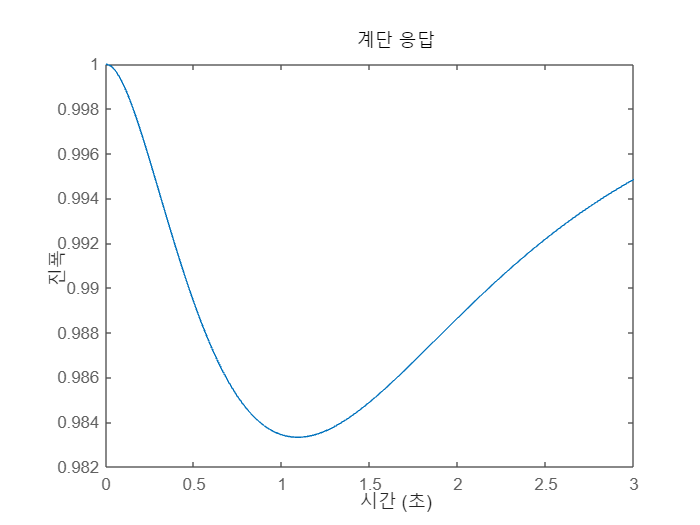

step(sys_cl, 3)

sys_cl_info = stepinfo(sys_cl);
Settlingtime = sys_cl_info.SettlingTime

Settlingtime = 0

PowerOverShoot = sys_cl_info.Overshoot  %모든 조건을 만족한다.

PowerOverShoot = 0